clc;clear;close all;

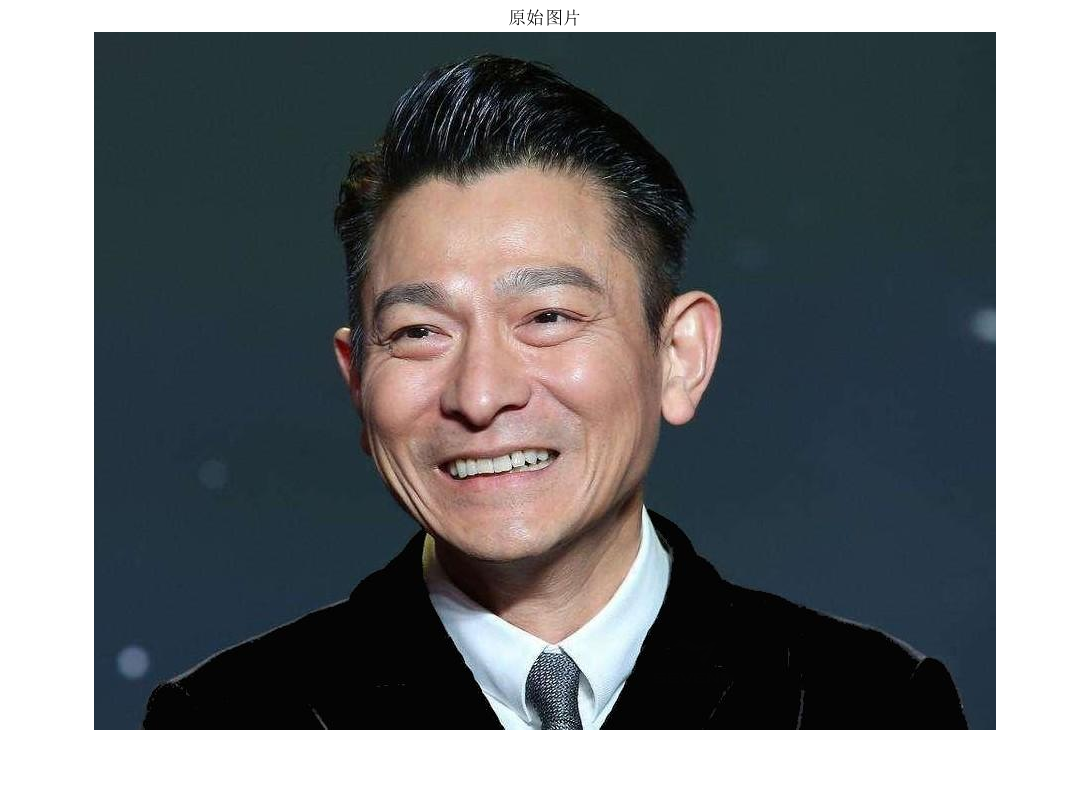



image=imread('05-刘德华.tif');
figure;
imshow(image);
title('原始图片');

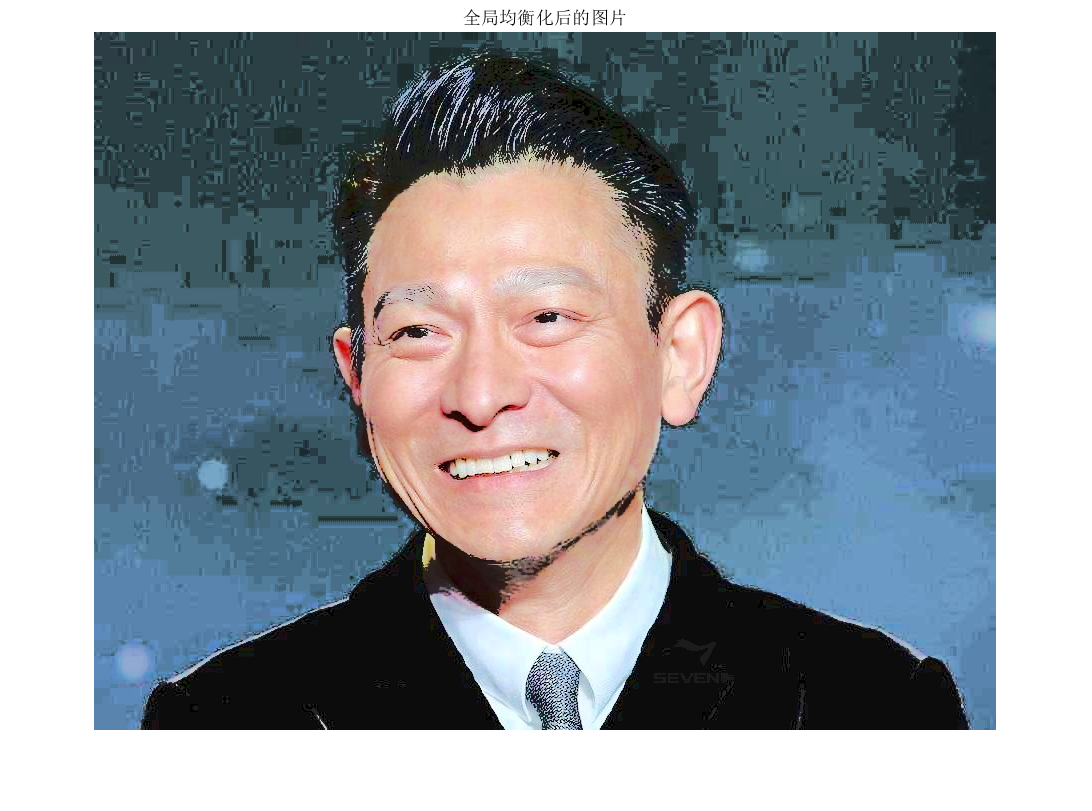

%转为hsv图像
ImgHSV = rgb2hsv(image);



newmap=ImgHSV;
%对明度进行均衡化
newmap(:,:,3) = histeq(ImgHSV(:,:,3));

newmap=hsv2rgb(newmap);%转为rgb图像
figure;
imshow(newmap);
title('全局均衡化后的图片');

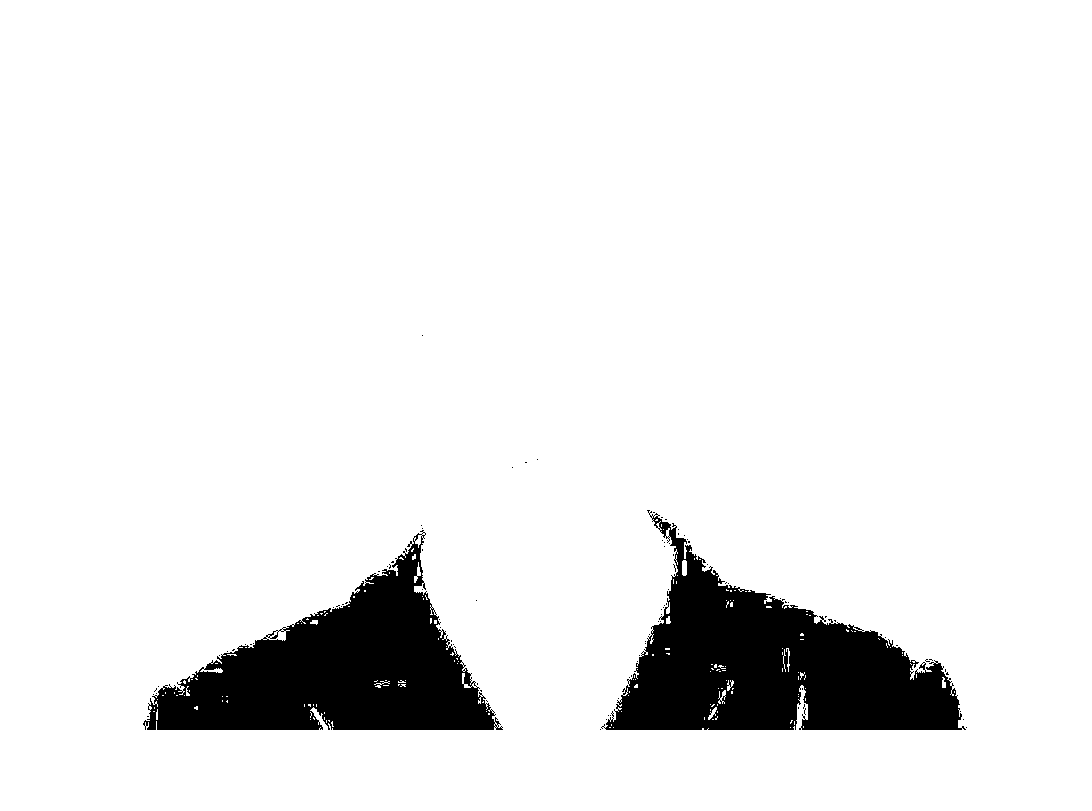

%取出图像明度分量
tmp=double(ImgHSV(:,:,3));
I2 = imbinarize(tmp,0.02);%对图像二值化
I2(1:300,:)=1;%去除头发干扰
I2=double(I2);
     
figure;
imshow(I2);

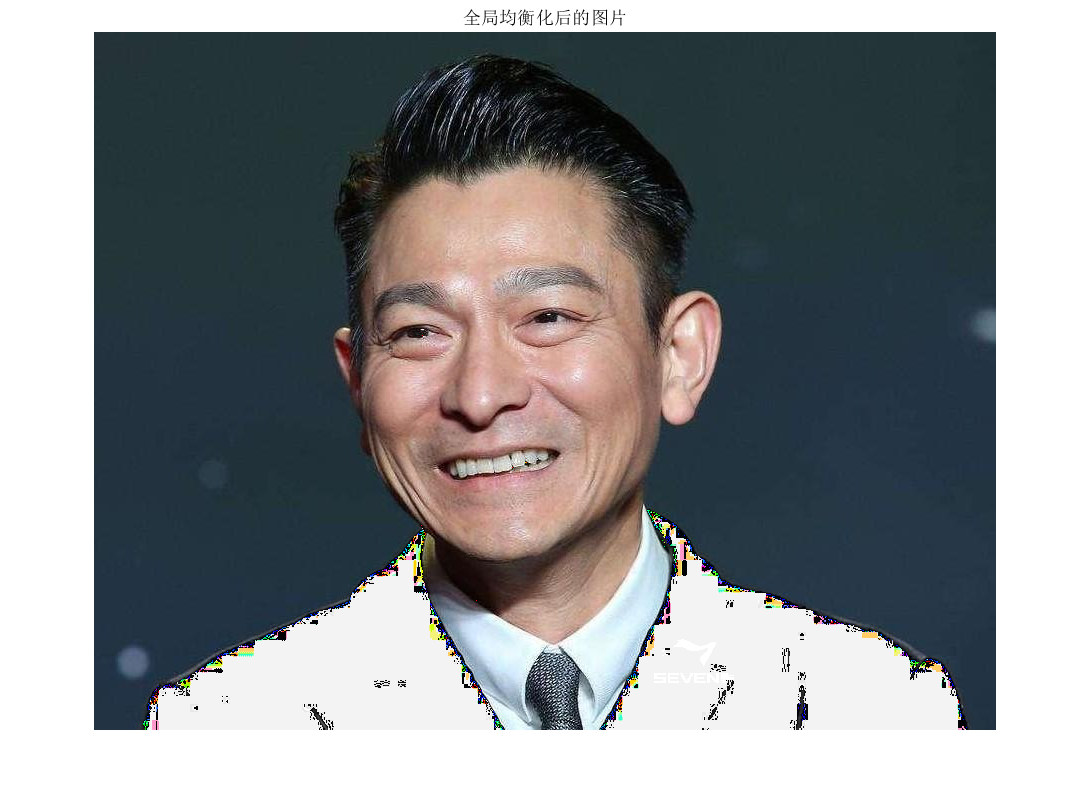


newmap=ImgHSV;
%对明度进行均衡化
newmap(:,:,3) = histeq(tmp.*(1-I2)).*(1-I2)+tmp.*I2;

newmap=hsv2rgb(newmap);%转为rgb图像
figure;
imshow(newmap);
title('局部均衡化后的图片');